clc;
clear all;
close all;

## generate data

tic

s=tf('s');
num=[0 1 3 7];
den=[1 8 -0.05 7];
sys_cont_open=tf(num,den);

sys_cont_open =
 
       s^2 + 3 s + 7
  ------------------------
  s^3 + 8 s^2 - 0.05 s + 7
 
Continuous-time transfer function.



fb_openloop = bandwidth(sys_cont_open);
T_s=0.05*2*pi/fb_openloop;
sys_dis_open = c2d(sys_cont_open, T_s,'zoh')

sys_dis_open =
 
   0.1572 z^2 - 0.2038 z + 0.08298
  ----------------------------------
  z^3 - 2.145 z^2 + 1.349 z - 0.1674
 
Sample time: 0.22343 seconds
Discrete-time transfer function.



[c,d]=tfdata(sys_dis_open,'v')

c =          0    0.1572   -0.2038    0.0830


d =     1.0000   -2.1452    1.3490   -0.1674


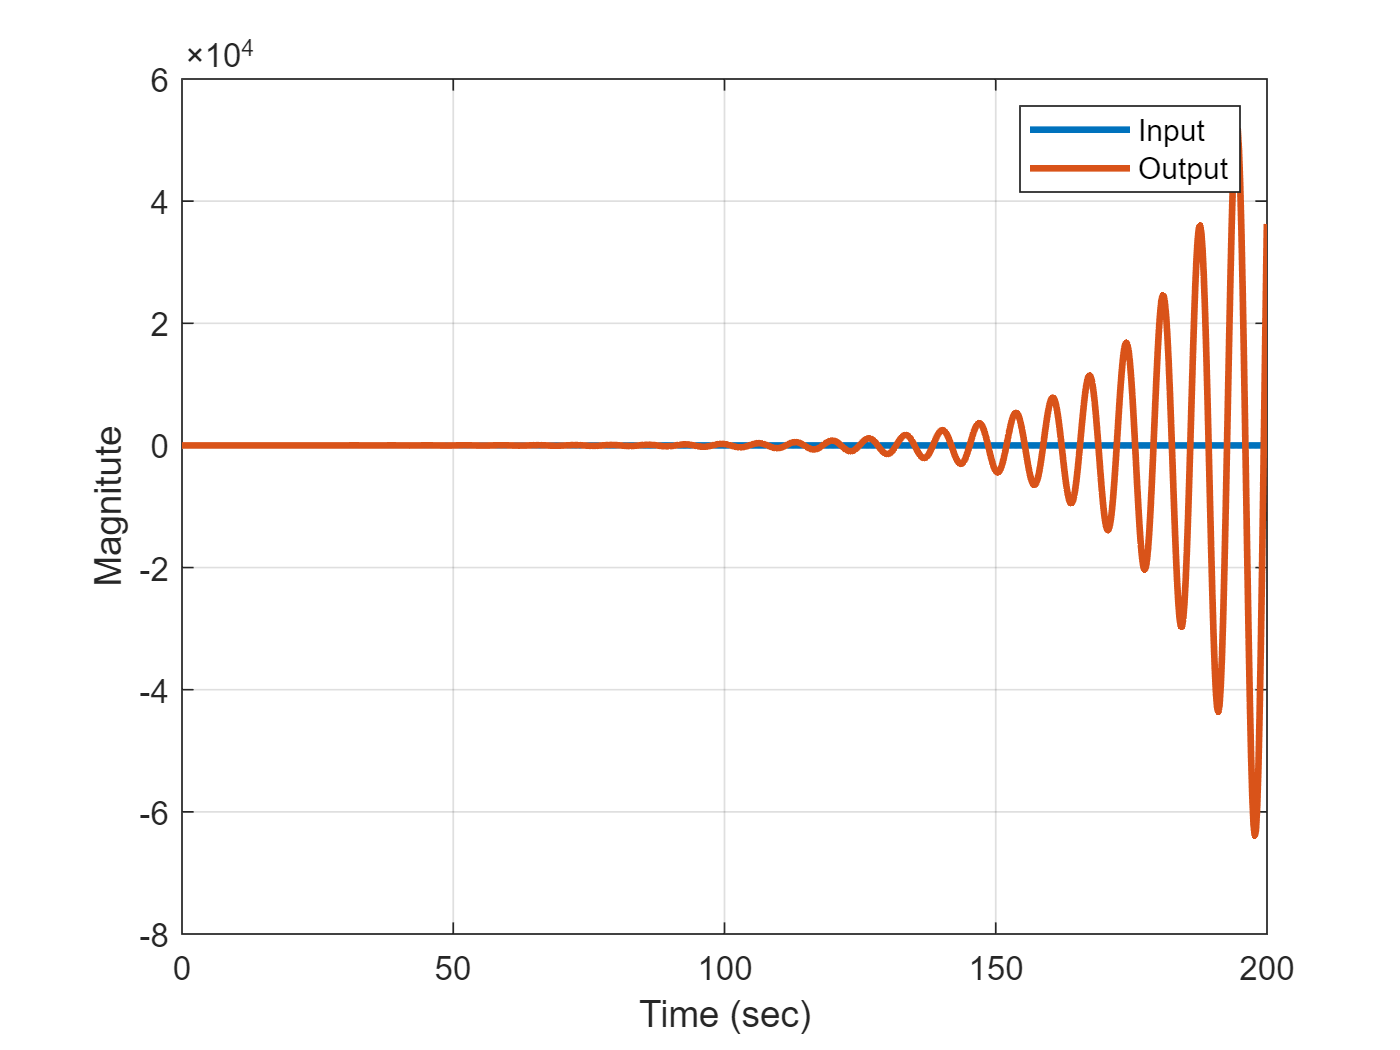

tfinal=200;
t = 0:T_s:tfinal;
u = gensig('sine' , tfinal/20 , tfinal ,T_s);
Noise=(-0.2+(0.2+0.2)*rand(numel(t),1));
u=u+Noise;
y = lsim(sys_dis_open,u ,t);
plot(t,u ,t , y ,'LineWidth',2) ;
xlabel('Time (sec)') ;
ylabel('Magnitute') ;
grid on
legend('Input','Output') ;

N = numel(y) ;
Parameters_in_den=3

Parameters_in_den = 3

Parameters_in_num=3

Parameters_in_num = 3

Nv=Parameters_in_num+Parameters_in_den;
theta(:,1:Nv) = zeros(Nv , Nv) ;
P = 1e12*eye(Nv) ;
phi=[];
for i = (max(Parameters_in_num,Parameters_in_den)+1):N
    phi(:,i) = [[y(i-1:-1:i-Parameters_in_den)]' , [u(i-1:-1:i-Parameters_in_num)]']';
    K = P*phi(:,i)*(1+phi(:,i)'*P*phi(:,i))^(-1) ;
    P = (eye(Nv) - K*phi(:,i)')*P ;
    theta(:,i) = theta(:,i-1) + K*(y(i) - phi(:,i)'*theta(:,i-1)); 
end

Bode

ident_dis = tf(theta((Parameters_in_num+1):end,end)' ,[1 -theta(1:Parameters_in_num ,end)'], T_s)

ident_dis =
 
   0.1572 z^2 - 0.2038 z + 0.08298
  ----------------------------------
  z^3 - 2.145 z^2 + 1.349 z - 0.1674
 
Sample time: 0.22343 seconds
Discrete-time transfer function.



ident_analog = d2c(ident_dis)

ident_analog =
 
       s^2 + 3 s + 7
  ------------------------
  s^3 + 8 s^2 - 0.05 s + 7
 
Continuous-time transfer function.



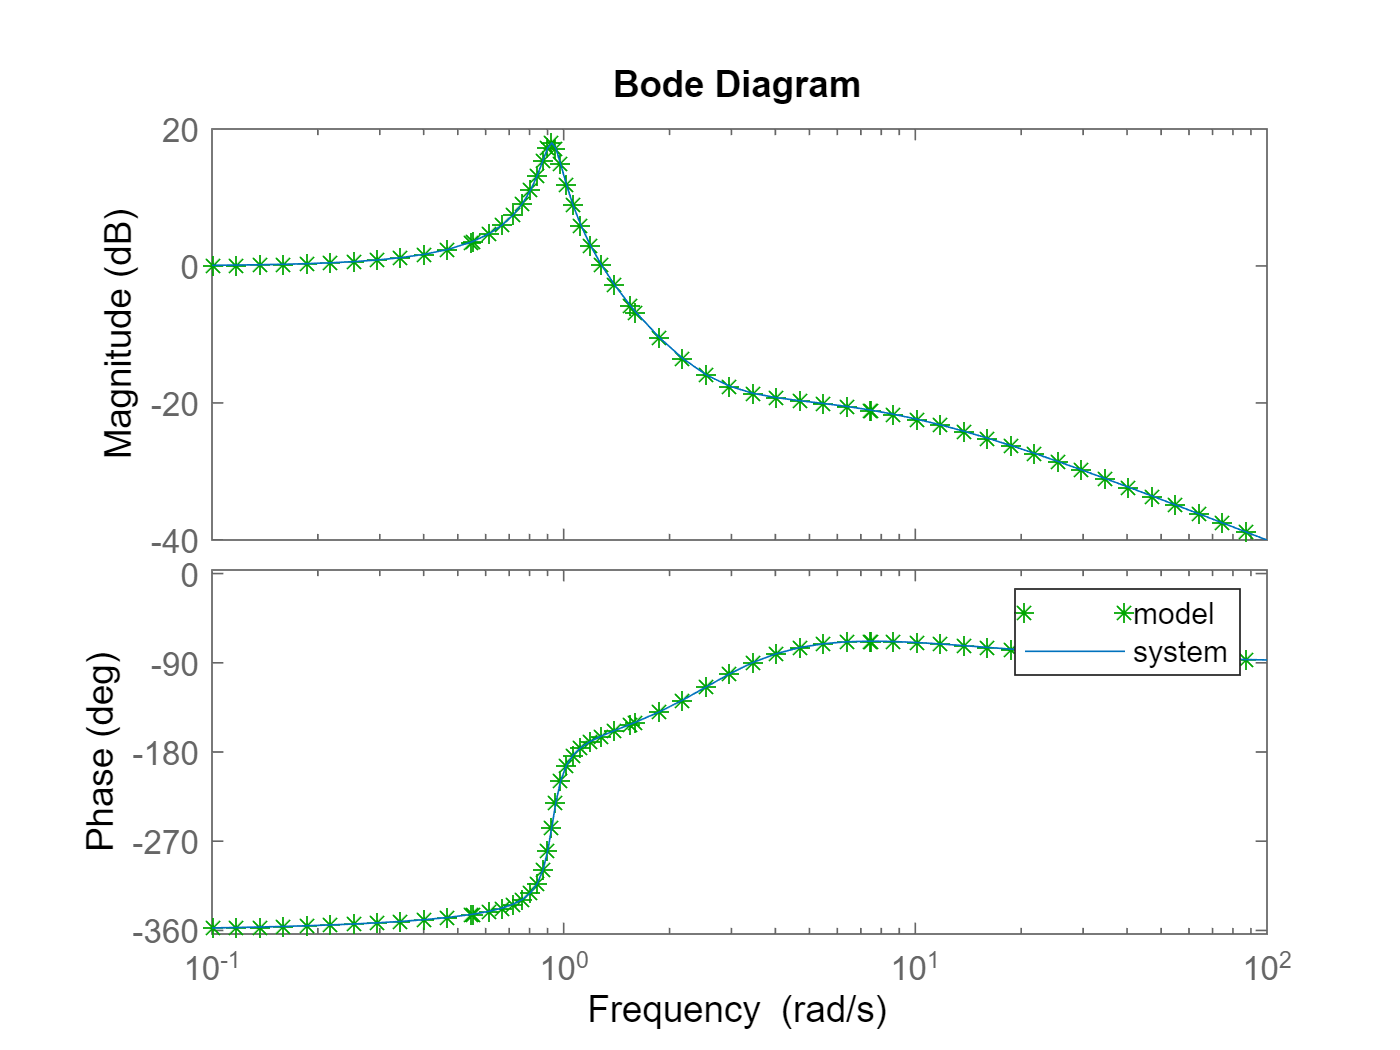

bode(ident_analog ,'g*',sys_cont_open)
legend('model ','system')

RLS Convergence

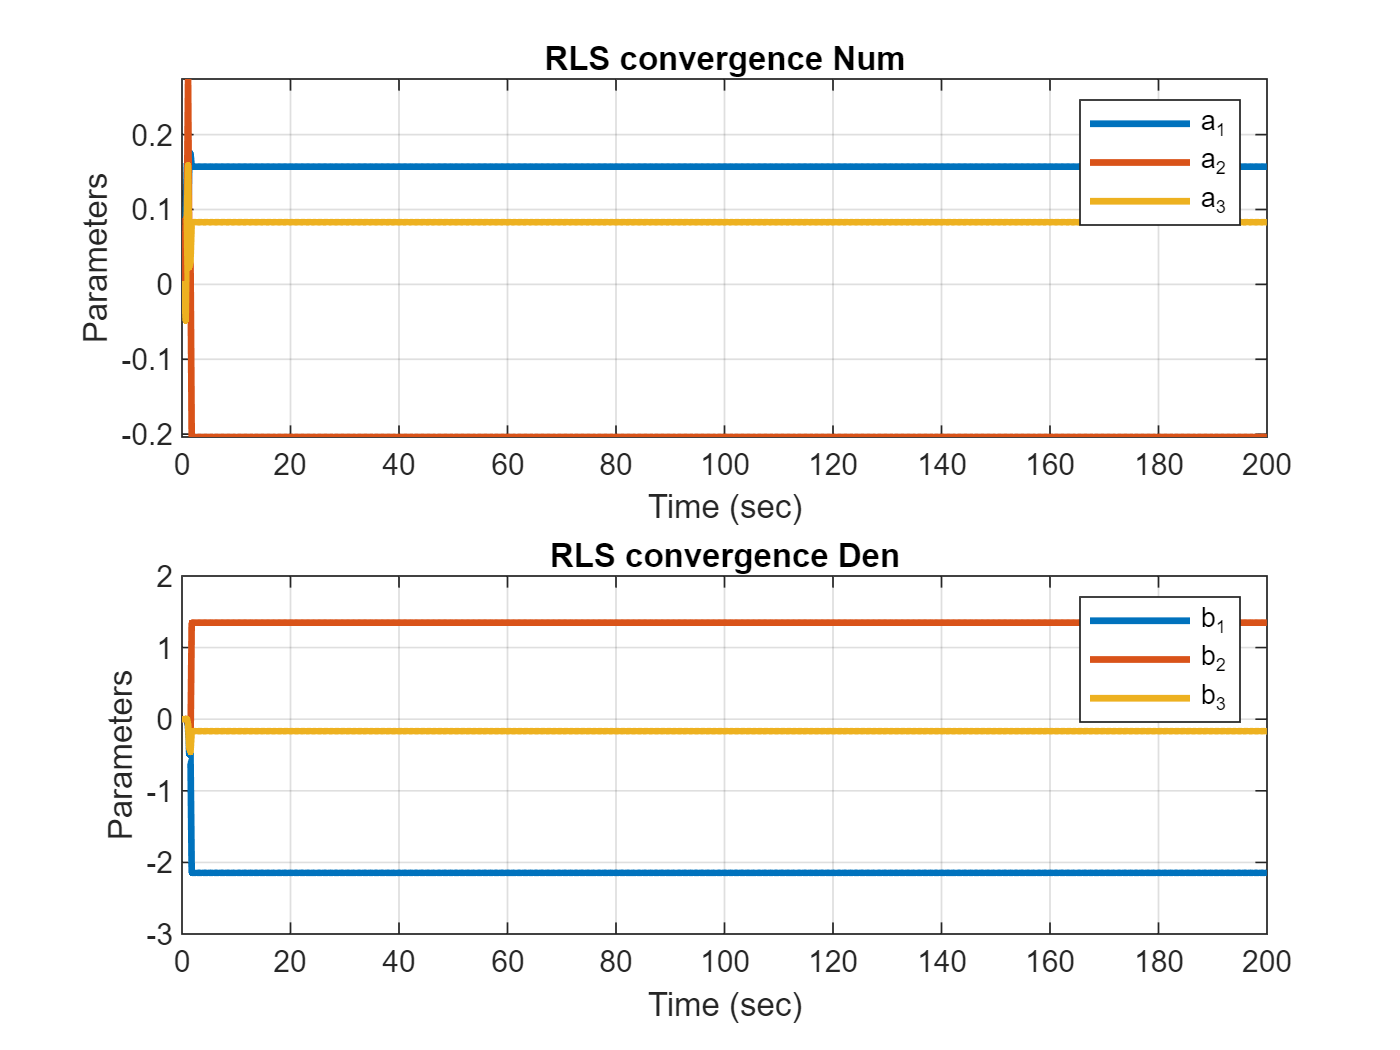

subplot(2,1,1)
plot(t , theta((Parameters_in_num+1):end,:) , 'LineWidth' , 2) ;
xlabel('Time (sec)') ;
ylabel('Parameters') ;
title('RLS convergence Num') ;
grid on
legend('a_1','a_2','a_3')
% xlim([0 6])
% ylim([-0.5 0.5])
%--------------------------------------------------------------
subplot(2,1,2)
plot(t , -theta(1:Parameters_in_num ,:) , 'LineWidth' , 2) ;
xlabel('Time (sec)') ;
ylabel('Parameters') ;
title('RLS convergence Den') ;
grid on
legend('b_1','b_2','b_3')

% xlim([0 6])
% ylim([-2 2])

toc

Elapsed time is 8.971559 seconds.
